# Notebook 1: SVM Kernel Exploration

                The purpose of this notebook is to try and determine the differences in the different SVM kernels that will be used in the kernel functions. The different kernel functions that will be explored for performance in kxcorr() function will be the RBF or gaussian_kernel, the cubic kernel, and the linear absolute value kernel. Those are defined as the following:

        RBF : 

                
$$K(x,y) = exp(\frac{-(x^2 + y^2)}{2\sigma})$$


        Cubic kernel:

                
$$K(x,y) = -(x \odot y + 1)^3$$


        Linear-absolute value kernel:

                
$$K(x,y) = |(x + y)|$$


Indicating that $x \odot y$ is the equivalent of the element wise matrix multiplication of the signal vectors. They must be the same length, so the ref signal must be zero-padded. 

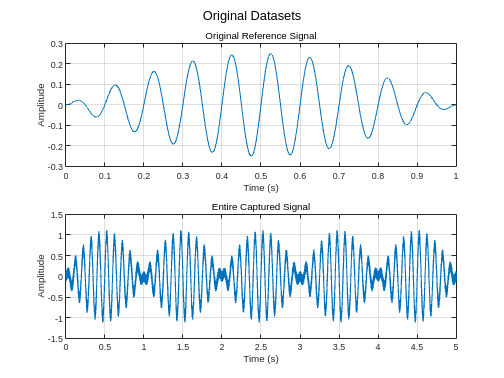

% --Setup
    clear; clc; format compact; close all; 
    % cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

    % --Plot
        figure()
        subplot(2,1,1)
        plot(t,ref_signal)
            hold on
            grid on
            subtitle('Original Reference Signal')
            ylabel("Amplitude")
            xlabel("Time (s)")

% --Creating sample signal
    t1 = 0:1/fs:5;
    amplitude = 1;
    envelope = amplitude.* sin(pi*t1);
    signal = envelope .* sin(f*t1);
    noisy_signal = randi(100,1,length(t1))./400 + signal;
    noisy_signal = noisy_signal - mean(noisy_signal);

% --Plotting
    subplot(2,1,2)
    plot(t1 , noisy_signal)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Amplitude")
        subtitle("Entire Captured Signal")
        sgtitle("Original Datasets")

## Exploring Linear Abs Value Kernel

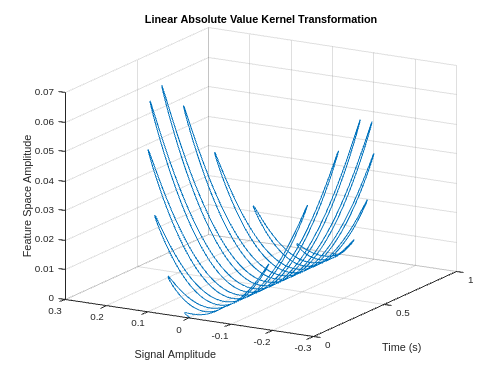

% --Find L-Abs Kernel of the function
    f_sig = fft(ref_signal);
    kf = Labs_kernel(f_sig,f_sig);

% --Plot kernel
    figure()
    plot3(t, ref_signal, kf)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Feature Space Amplitude")
        title("Linear Absolute Value Kernel Transformation")
        view([-60 20])

This could be good for white noise where we have a cyclic signal where we are trying to distinguish the cyclic signal vs. random noise. Lets look at what the random noise would look like under the kernel transformation. 

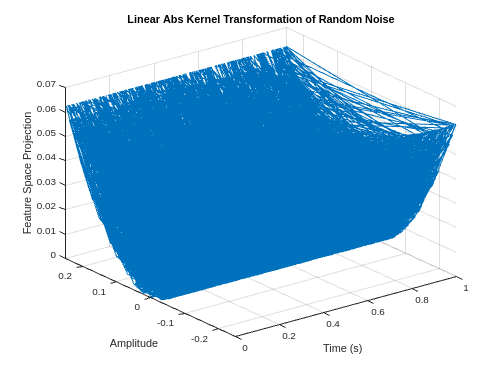

% --Creating random noise
    random_noise = randi([-25 25], 1, 10001)/100;
    f_rando = fft(random_noise);

% --Finding the kernel
    kf = Labs_kernel(f_rando, f_rando);

% --Plot
    figure()
    plot3(t, random_noise, kf)
        xlabel("Time (s)")
        ylabel("Amplitude")
        zlabel("Feature Space Projection")
        hold on
        grid on
        title("Linear Abs Kernel Transformation of Random Noise")

The kernel transformation of random noise of the same amplitude has half the amplitude of the linear absolute value kernel. This bodes well for the signal detection, because our deterministic signals are going to be raised above the noise creating the ability to linearly separate and detect the signals. The raised feature space could allow the correlation algorithm to pick out signals better. This could be good for white noise detection algorithms. This may not be so good for colored noise algorithms. 

## Exploring The Cubic Kernel

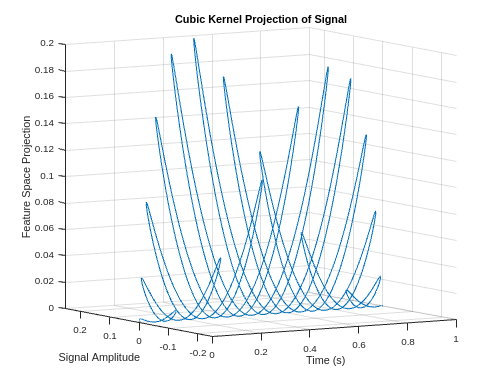

% --Cubic kernel
    kf = cubic_kernel(f_sig, f_sig);

% --Plot
    figure()
    plot3(t, ref_signal, kf)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Feature Space Projection")
        title("Cubic Kernel Projection of Signal")   
        view([-31 7])

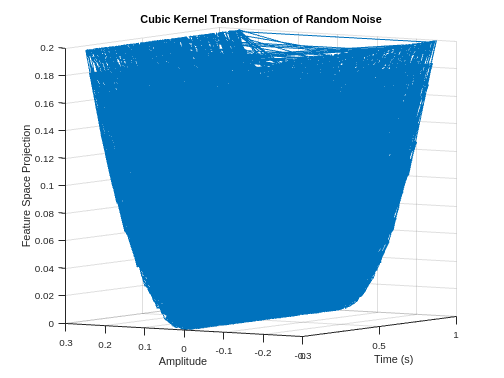

% --Using cubic kernel on random noise
    kf = cubic_kernel(f_rando, f_rando);

% --Plot random noise
    figure()
    plot3(t, random_noise, kf)
        xlabel("Time (s)")
        ylabel("Amplitude")
        zlabel("Feature Space Projection")
        hold on
        grid on
        title("Cubic Kernel Transformation of Random Noise")
        view([-57 5])

This also has a similar trend vs. the random noise that will allow for signals to be raised below the noise in the feature space where we can see the deterministic part of the signal away from the random nose where the signal will be centered at 0 and the noise will be centered at the amplitude of the kernel transformation of signal at t = 0. 

## Exploring the RBF Function

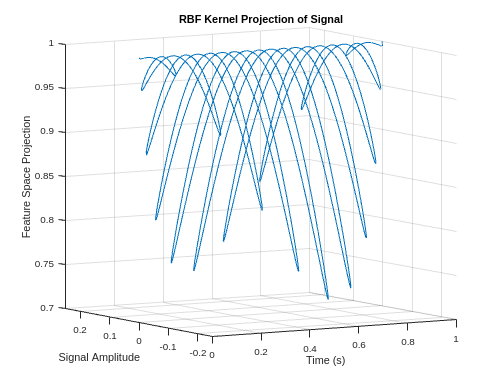

% --Finding kernel of data
    kf = gaussian_kernel(f_sig, f_sig, 0.2);

% --Plot
    figure()
    plot3(t, ref_signal, kf)
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Feature Space Projection")
        title("RBF Kernel Projection of Signal")   
        view([-31 7])

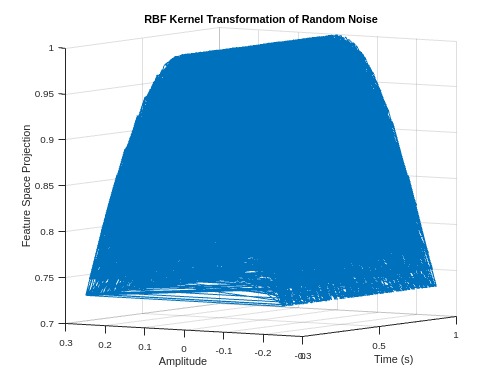

% --Using RBF kernel on random noise
    kf = gaussian_kernel(f_rando, f_rando, 0.2);

% --Plot random noise
    figure()
    plot3(t, random_noise, kf)
        xlabel("Time (s)")
        ylabel("Amplitude")
        zlabel("Feature Space Projection")
        hold on
        grid on
        title("RBF Kernel Transformation of Random Noise")
        view([-57 5])

                Because of the relative amplitudes of the noise, we cannot say that there is a benefit in terms of the RBF kernel when defining the hyperplane for the detection of signals because the data still falls in line with the deterministic signal. This could indicate poor performance for white noise but could be more beneficial for colored noise as most of the colored noise is deterministic in nature. The amplitude of the noise transformation lies directly in the middle of the signal transformation. Because of the properties of the RBF with scale-space filtering, we could use this for colored noise and therefore could see a higher performance with the deterministic colored noise in signal detection vs. the other kernel functions. 

                The RBF will transform the edges of the signals more than the center of the signals which could possibly help with signal detection with colored noise with negative dB. This goes hand in hand with the scale space filtering idea of the signals.

                The RBF Kernel is a special case in the kernels that it has an extra parameter named $\sigma$ which is the gaussian width. The larger the value the larger the width of the kernel. The larger the sigma value the smaller the amplitude of the kernel transform will be. The higher the value, typically the worse distinction between the noise and the signal is.

### 2D Version of the RBF Kernel

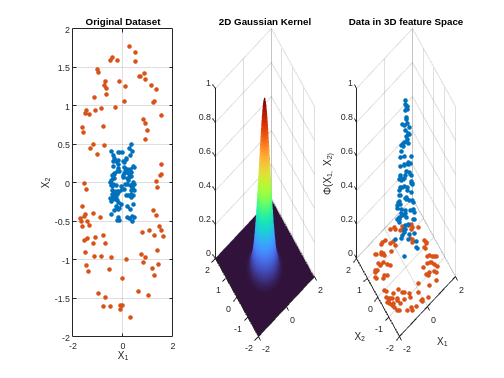

% --Setup
    step = 100;
    sigma = 0.1;
    x = -2:1/step:2;
    values_x = rand([1, 100]) - 0.5;
    values_y = rand([1,100]) - 0.5;

    r = 0.8 + sqrt(rand([1,100]));
    theta = rand([1,100]) .* 2 .* pi;

    values_x_2 = r.*cos(theta);
    values_y_2 = r.*sin(theta);

% --Plot original set
    figure()
    subplot(1,3,1)
    plot(values_x,values_y,'.', 'MarkerSize',14)
        hold on
        grid on
        xlim([-2 2])
        ylim([-2 2])

    plot(values_x_2, values_y_2, '.', 'MarkerSize', 14)
        title('Original Dataset')
        xlabel('X_1')
        ylabel('X_2')
% --Calculating kernel
    [X,Y]=meshgrid(x,x);
    k = exp(-(X.^2 + Y.^2) ./ (2*sigma));
    
    subplot(1,3,2)
    surf(X,Y,k)
        shading interp
        title('2D Gaussian Kernel')
        colormap turbo
        
% --Calculating projection of datasets
    X = [values_x];
    Y = [values_y];
    k = exp(-(X.^2 + Y.^2) ./ (2*sigma));

    X2 = [values_x_2];
    Y2 = [values_y_2];
    k2 = exp(-(X2.^2 + Y2.^2) ./ (2*sigma));

% --Plot Projection
    subplot(1,3,3)
    plot3(X,Y,k,'.','MarkerSize', 14)
        hold on
        grid on

    plot3(X2,Y2,k2,'.','MarkerSize', 14)
    title('Data in 3D feature Space')
    xlabel('X_1')
    ylabel('X_2')
    zlabel('\Phi(X_1, X_2)')

### Variation of the RBF with $\sigma$ parameter

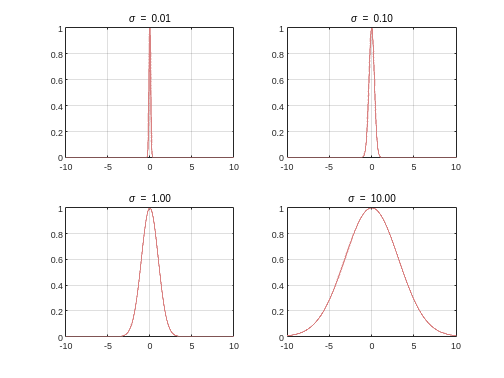

% --Parameters
    step = 1000;
    sigma = [0.01, 0.1, 1, 10];
    x = -10:1/step:10;
    solution = [];

% --Calculate gaussian to show the spread of sigma
    for i = 1:length(sigma)
        
        k = exp( -(x.^2) ./ (2*sigma(i)) );
        
        subplot(2,2,i)
        plot(x,k,'LineWidth',1.5,'Color',[0.85 0.5 0.5])
            grid on
            hold on
            str = sprintf("\\sigma = %2.2f", sigma(i));
            subtitle(str)

    end

## Creating Basic Signal With White Noise

% --zero-padding signal
    long_signal = [zeros(1, 10000), ref_signal, zeros(1, 10000)];
    random_noise_long = randi([-250 250], 1, length(long_signal))/1000;
    long_noisy_signal = long_signal + random_noise_long;
    time_long = 0:1/fs:(length(long_signal) - 1) / fs;

% --Statistical properties of the white noise
    Expected_val = mean(random_noise_long)

Expected_val = -4.2759e-04

    standard_dev = std(random_noise_long)

standard_dev = 0.1455

% --Calculating SNR values
    noise_power = sum(random_noise.^2)/(2*length(random_noise) + 1);
    signal_power = sum(long_signal.^2)/(2*length(long_signal) + 1);
    SNR = 10*log10(signal_power/noise_power)

SNR = -6.2496

## Finding Kernel Transformations of the Signal

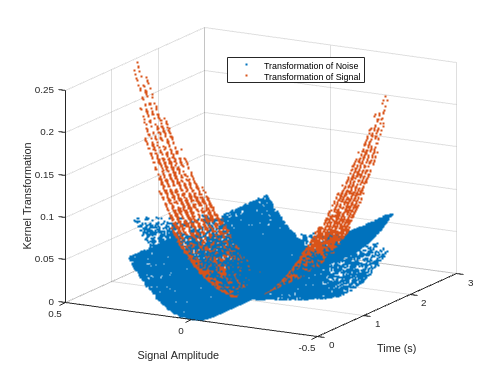

% --Taking fft_s
    f_long_signal = fft(long_noisy_signal);
    f_noise = fft(random_noise_long);

% --Finding Kernel Transformations
    kf = Labs_kernel(f_long_signal,f_long_signal);

% --Pull out parts of the signal
    kf_signal = kf(:,10002:20002);
    time_new = 1:1/fs:2;
    kf_noise = Labs_kernel(f_noise, f_noise);

% --Plotting
    figure()
    plot3(time_long, long_noisy_signal, kf_noise, '.')
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        
    plot3(time_new, long_noisy_signal(:,10002:20002), kf_signal, '.')
        legend("Transformation of Noise","Transformation of Signal")
        view([-61.200 18.667])
        legend("Position", [0.4524,0.78042,0.27128,0.067857])

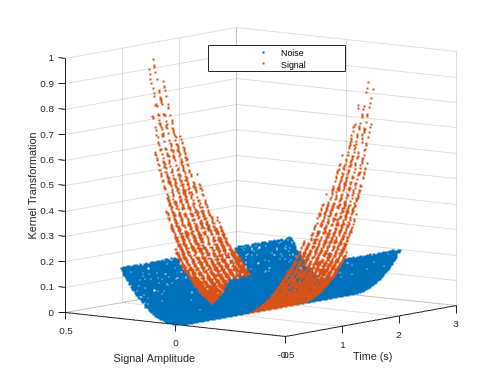

% --Cubic Kernel Transformation
    kf = cubic_kernel(f_long_signal, f_long_signal);

% --Pull out parts of the signal
    kf_signal = kf(:,10002:20002);
    time_new = 1:1/fs:2;
    kf_noise = cubic_kernel(f_noise, f_noise);

% --Plotting
    figure()
    plot3(time_long, long_noisy_signal, kf, '.')
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        
    plot3(time_new, long_noisy_signal(:,10002:20002), kf_signal, '.')
        view([-52.200 8.667])
        legend("Position", [0.4147,0.81217,0.27128,0.067857])
        legend('Noise','Signal')

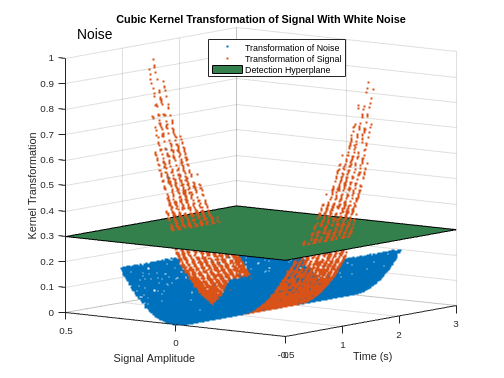

% --Creating the hyperplane
    x = [0 3];
    y = [-0.5 0.5];
    z = [0.3 0.3
         0.3 0.3];
    figure()
    plot3(time_long, long_noisy_signal, kf, '.')
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        title("Cubic Kernel Transformation of Signal With White Noise")
        
    plot3(time_new, long_noisy_signal(:,10002:20002), kf_signal, '.')
        view([-52.200 8.667])
        legend("Position", [0.4147,0.81217,0.27128,0.067857])

    surf(x, y, z, 'FaceColor',[0.2 0.5 0.3])
        legend("Transformation of Noise", "Transformation of Signal", "Detection Hyperplane")
        text(1, -0.1, 1.5, "Signal",'FontSize',14)
        text(0, 0.45, 1.1, "Noise","FontSize",14)

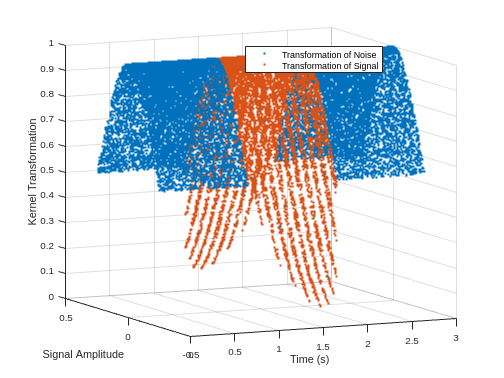

% --RBF Kernel Transformation
    kf = gaussian_kernel(f_long_signal, f_long_signal, 0.1);

% --Pull out parts of the signal
    kf_signal = kf(:,10002:20002);
    time_new = 1:1/fs:2;

% --Plotting
    figure()
    plot3(time_long, long_noisy_signal, kf, '.')
        hold on
        grid on
        xlabel("Time (s)")
        ylabel("Signal Amplitude")
        zlabel("Kernel Transformation")
        
    plot3(time_new, long_noisy_signal(:,10002:20002), kf_signal, '.')
        legend("Transformation of Noise","Transformation of Signal")
        view([-25.200 9.334])
        legend("Position", [0.48812,0.80952,0.27128,0.067857])

## Frequency Domain Versions of Kernels

The time domain versions of the kernels are as follows:

         RBF : 

                
$$K(x,y) = exp(\frac{-(x^2 + y^2)}{2\sigma})$$


        Cubic kernel:

                
$$K(x,y) = -(x \odot y + 1)^3$$


        Linear-absolute value kernel:

                
$$K(x,y) = |(x + y)|$$


The time domain versions can be then converted into the frequency domain as follows:

        L-Abs kernel:

                
$$\hat{K}_{xy} = |\hat{X} - \hat{Y}^*|$$


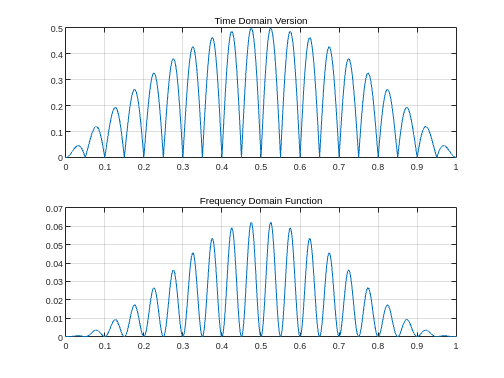

% --Proof of L-Abs equivalence
    Time_domain_L_Abs = abs(ref_signal + ref_signal);
    f_domain_L_abs = Labs_kernel(f_sig, f_sig);

% --Plotting
    figure()
    subplot(2,1,1)
    plot(t, Time_domain_L_Abs)
        hold on
        grid on
        subtitle("Time Domain Version")
    subplot(2,1,2)
    plot(t, f_domain_L_abs)
        hold on
        grid on
        subtitle("Frequency Domain Function")

                In order to properly compute this we would need to convert to and from the f-domain multiple times to remain having the output as a frequency function, this is not a pro-and computing the kernels in the frequency domain may actually be less important than previously thought becuase of the complexity of the calculations within the frequency domain. As a verdict we should pass the function the time domain functions and only use the frequency domain functions when needed. 

Final Verdict: Compute the signal kernels in the time domain and then compute the fft of the signal and then spit them out in the time domain

####         Gaussian Kernel Definition:

function kf = gaussian_kernel(xf, yf, sigma)    % TIME DOMAIN

    % --Perform Auto and Cross correlations
        x = ifft(xf);
        y = ifft(yf);
    
    % --Find Kernel
        kf = exp(-(x.^2 + y.^2) ./ (2*sigma));

end

####         L-abs Kernel Definition:

        This is the definition of the kernel when we are working within the frequency domain. This is purey for the ease of calculation. In order to do this problem not in the frequency domain, we can find the equivalent using the following formula: $|x + y|$ which == $|\hat{X} - \hat{Y}^*
|$ in the frequency domain

function kf = Labs_kernel(xf, yf)
    
    % --Setup
        xy = ifft(xf - conj(yf));

    % --Find the kernel
        kf = abs(xy);

end

####         Cubic Kernel Definition:

function kf = cubic_kernel(xf, yf)

    % --Setup parameters
        x = ifft(xf);
        y = ifft(yf);

    % --Find Kernel
        kf = (x.*y + 1).^3;
        kf = kf - 1;

end